addpath ../Tool
addpath ../Informs
addpath ../Model
addpath ../Data 
addpath ../ValidationFunctions

load('coInform.mat')

T = InformContainer{18}.T;
T = gsua_load(T);

Setting environment to work with user-defined function


## Variation of $\lambda_{fq}$ 

n = 50;
a = 0.2; b = 0.3;
Nominal1 = repmat(T.Nominal, 1, n);
Nominal1(5,:) = (b-a)*rand(n,1)+a;
Nominal1(end,:) = 607;

a = 0.01; b = 0.2;
Nominal2 = repmat(T.Nominal, 1, n);
Nominal2(5,:) = (b-a)*rand(n,1)+a;
Nominal2(end,:) = 680;

D = 685;

ysim2 = simulateScnarios(T, Nominal1, Nominal2, D, ydata);

Setting environment to work with user-defined function


For professional Matlab assistance, please contact <a href="https://UndocumentedMatlab.com/consulting">https://UndocumentedMatlab.com/consulting</a>


## Variation of $\lambda_{qf}$ 

Setting environment to work with user-defined function


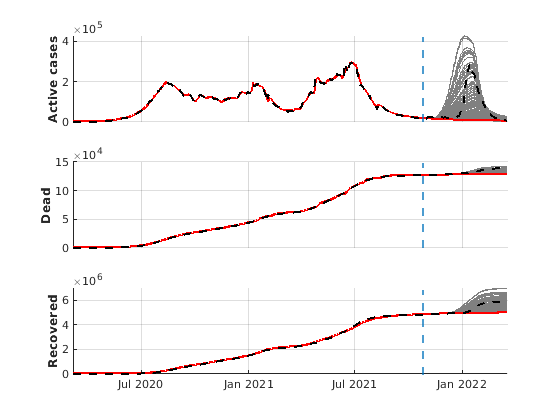

n = 100;
a = 0.2; b = 0.4;
Nominal1 = repmat(T.Nominal, 1, n);
Nominal1(1,:) = (b-a)*rand(n,1)+a;
Nominal1(end,:) = 607;

a = 0.4; b = 0.5;
Nominal2 = repmat(T.Nominal, 1, n);
Nominal2(1,:) = (b-a)*rand(n,1)+a;
Nominal2(end,:) = 680;

ysim2 = simulateScnarios(T, Nominal1, Nominal2, D, ydata);

## Combination of   $\lambda_{qf}$ and $z$

Setting environment to work with user-defined function


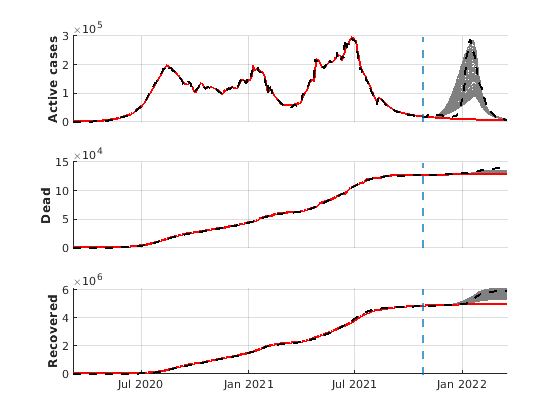

n = 100;
a = 25; b = 30;
Nominal1 = repmat(T.Nominal, 1, n);
Nominal1(1,:) = 0.2;
Nominal1(10,:) = (b-a)*rand(n,1)+a;
Nominal1(end,:) = 607;

a = 15; b = 20;
Nominal2 = repmat(T.Nominal, 1, n);
Nominal2(1,:) = 0.5;
Nominal1(10,:) = (b-a)*rand(n,1)+a;
Nominal2(end,:) = 680;

ysim2 = simulateScnarios(T, Nominal1, Nominal2, D, ydata);